# Natural Resources Management

# Final Project

addpath("utils\")

## Part 0. Data pre-processing

file = readmatrix("data\5. Jochenstein.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

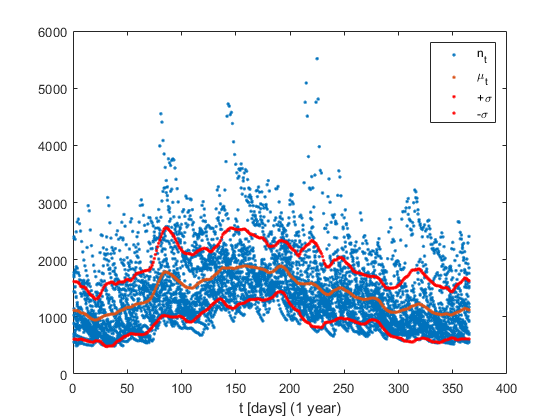

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

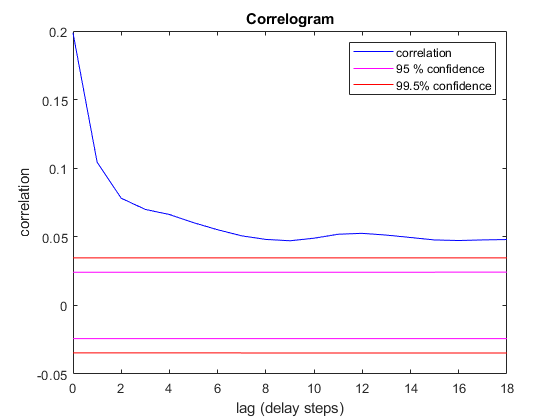

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

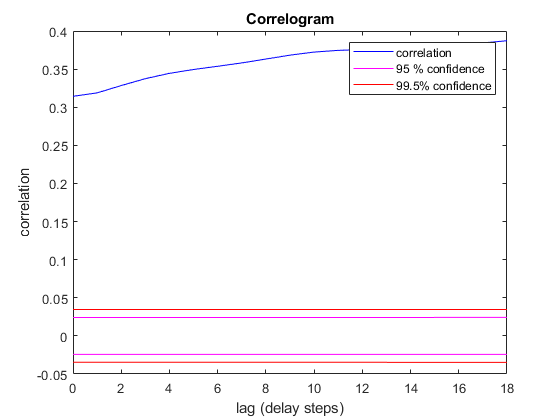

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

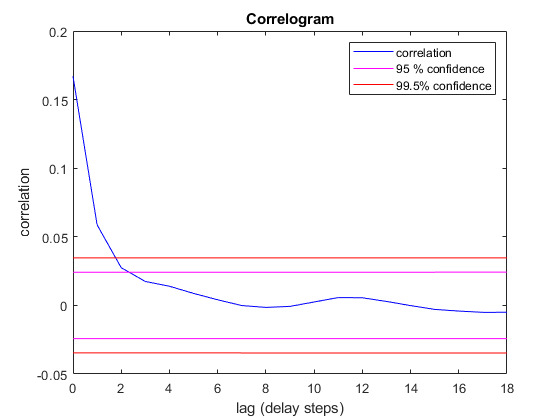

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

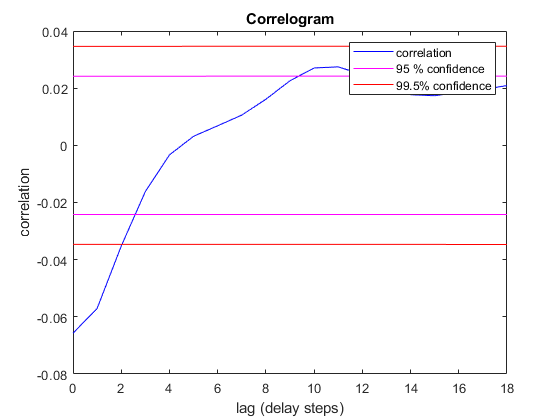

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (n)

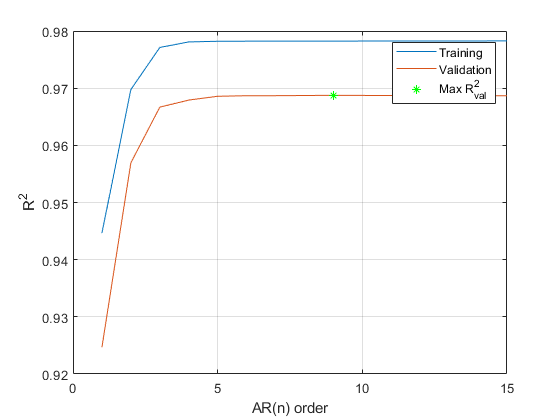

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx = 0.9708

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_val = 0.9626

#### Improper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(2:end,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx_imp = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx_imp = 0.9563

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_imp_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_imp_val = 0.9545

### Nonlinear models

#### Proper ANN

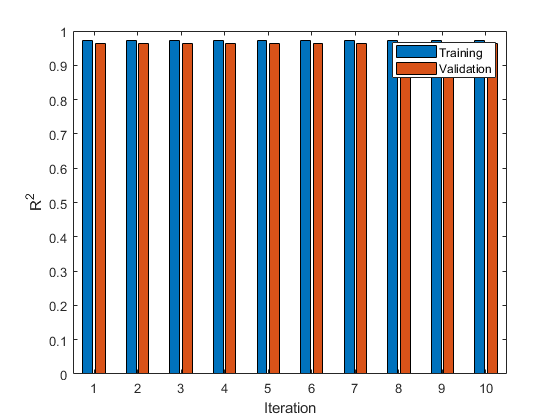

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
ann_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    r2_ann_prop(i) = getR2Performance(x_tr, y_ann_prop, mean_x, sigma_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_norm_val(1); y'];
    r2_ann_prop_val(i) = getR2Performance(x_val, y_ann_prop_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
        ann_opt_idx = i;
    end
    
end

figure; 
h = bar([r2_ann_prop, r2_ann_prop_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

#### Improper ANN

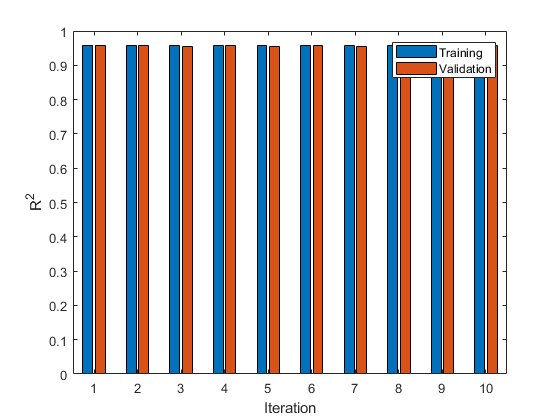

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
ann_improp_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    r2_ann_improp(i) = getR2Performance(x_tr, y_ann_improp, mean_x, sigma_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_norm_val(1); y'];
    r2_ann_improp_val(i) = getR2Performance(x_val, y_ann_improp_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
        ann_improp_opt_idx = i;
    end
    
end

figure; 
h = bar([r2_ann_improp, r2_ann_improp_val]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend()

#### CART

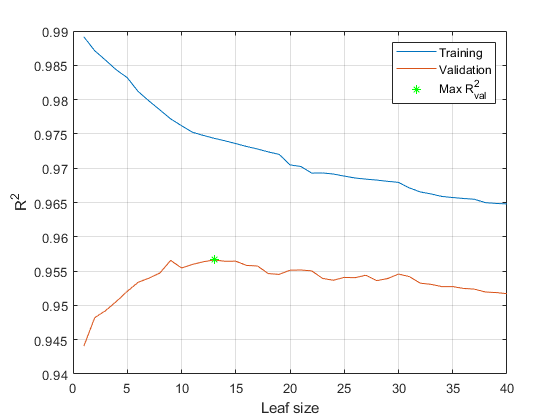

x_cart = [x_norm(1:end-1), u_norm(1:end-1,:)];
y_cart = x_norm(2:end);

x_cart_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
y_cart_val = x_norm_val(2:end);
    
max_leaf_size = 40;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);
leafsize_opt = 0;

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y = predict(T_i, x_cart);
    y_cart_predict = [x_norm(1); y];
    r2_cart(i) = getR2Performance(x_tr, y_cart_predict, mean_x, sigma_x);
    
%     Validation
    y = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_norm_val(1); y];
    r2_cart_val(i) = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
        leafsize_opt = i;
    end 
end

figure;
plot([r2_cart, r2_cart_val])
hold on
plot (leafsize_opt, r2_cart_val(leafsize_opt), '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('Leaf size');ylabel('R^2');
grid on

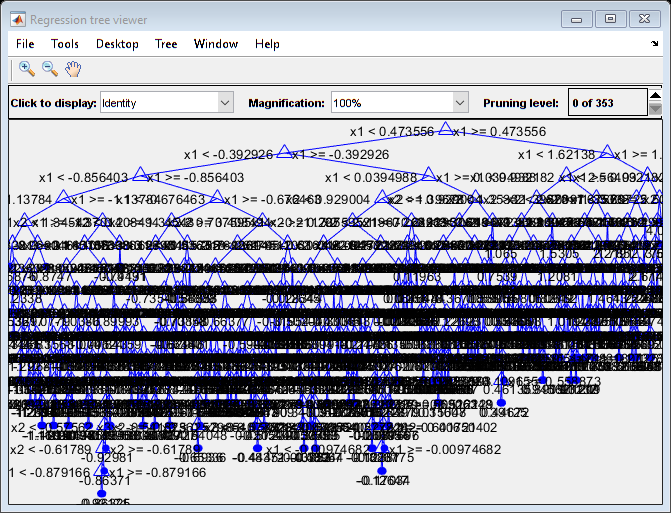

view(T_opt,'mode','graph')

T_opt.NumNodes

ans = 787

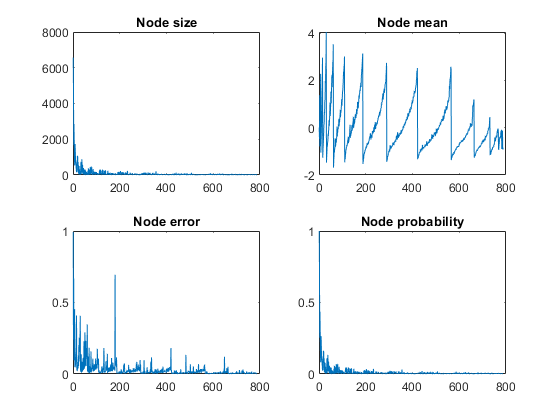

figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.040382 |       1.821 |    0.040382 |    0.040382 |            6 |


|    2 | Accept |    0.081619 |     0.23624 |    0.040382 |    0.043097 |          261 |


|    3 | Accept |    0.044361 |     0.20015 |    0.040382 |    0.045208 |           44 |


|    4 | Accept |     0.25202 |     0.13934 |    0.040382 |    0.040389 |         1667 |


|    5 | Best   |    0.039022 |     0.28558 |    0.039022 |    0.039036 |           15 |


|    6 | Accept |    0.050107 |     0.55208 |    0.039022 |    0.039059 |            1 |


|    7 | Accept |    0.043855 |     0.46652 |    0.039022 |     0.03908 |            3 |


|    8 | Best   |    0.038425 |     0.14523 |    0.038425 |    0.038559 |           11 |


|    9 | Accept |    0.038425 |     0.24389 |    0.038425 |    0.038505 |           11 |


|   10 | Accept |    0.038425 |     0.20065 |    0.038425 |     0.03848 |           11 |


|   11 | Accept |    0.038425 |     0.16029 |    0.038425 |    0.038466 |           11 |


|   12 | Accept |    0.054223 |    0.085806 |    0.038425 |    0.038491 |          103 |


|   13 | Accept |    0.041268 |     0.13765 |    0.038425 |    0.038488 |           26 |


|   14 | Accept |    0.046436 |     0.47734 |    0.038425 |    0.038492 |            2 |


|   15 | Accept |     0.68936 |     0.15148 |    0.038425 |    0.038437 |         3284 |


|   16 | Accept |     0.12873 |     0.10754 |    0.038425 |    0.038428 |          646 |


|   17 | Accept |    0.039537 |     0.22463 |    0.038425 |    0.038445 |            8 |


|   18 | Accept |    0.039116 |     0.12939 |    0.038425 |    0.038465 |           19 |


|   19 | Accept |    0.038917 |     0.22314 |    0.038425 |      0.0385 |           13 |


|   20 | Accept |    0.047488 |     0.11279 |    0.038425 |    0.038505 |           64 |


|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |    0.038765 |     0.12037 |    0.038425 |    0.038507 |           16 |


|   22 | Accept |    0.038917 |     0.12785 |    0.038425 |    0.038525 |           13 |


|   23 | Accept |    0.038563 |      0.2111 |    0.038425 |    0.038518 |           10 |


|   24 | Accept |    0.038563 |     0.14842 |    0.038425 |    0.038514 |           10 |


|   25 | Accept |    0.060871 |    0.090621 |    0.038425 |    0.038517 |          155 |


|   26 | Accept |     0.20323 |    0.060122 |    0.038425 |    0.038463 |          999 |


|   27 | Accept |    0.041727 |     0.11147 |    0.038425 |    0.038465 |           33 |


|   28 | Accept |    0.042453 |      0.4016 |    0.038425 |    0.038467 |            4 |


|   29 | Accept |    0.039122 |     0.15262 |    0.038425 |    0.038465 |           17 |


|   30 | Accept |    0.039733 |     0.11378 |    0.038425 |    0.038465 |           21 |


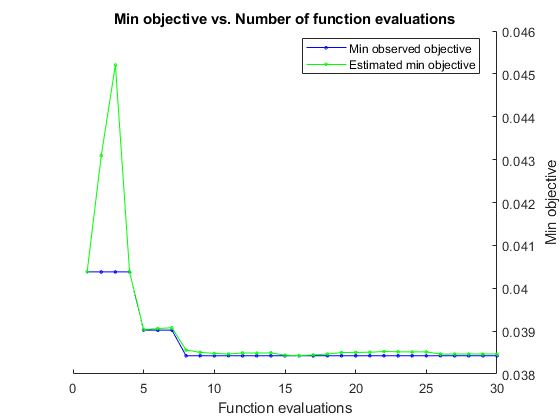

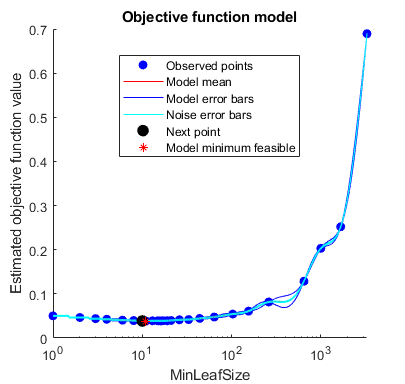


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 63.2607 seconds.
Total objective function evaluation time: 7.6387

Best observed feasible point:
    MinLeafSize
    ___________

        11     

Observed objective function value = 0.038425
Estimated objective function value = 0.038465
Function evaluation time = 0.14523

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        11     

Estimated objective function value = 0.038465
Estimated function evaluation time = 0.18098



T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_norm_val(1); y];
r2_cart_auto_val = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val)

r2_cart_auto_val = 0.9560

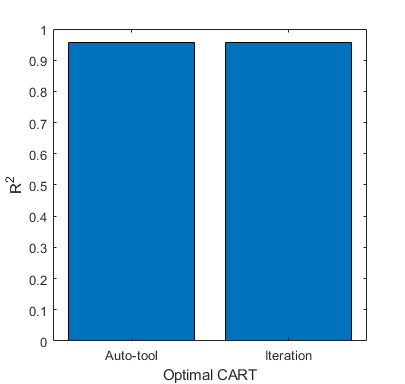

c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val])
xlabel('Optimal CART');ylabel('R^2');

### Models comparison

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1) Proper', ...
    'ARX(1,1) Improper', ...
    'ANN(3) Proper', ...
    'ANN(3) Improper', ...
    'CART', ...
    });
r2_index = [ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    r2_arx_imp, r2_arx_imp_val; ...
    r2_ann_prop(ann_opt_idx), r2_ann_prop_val(ann_opt_idx); ...
    r2_ann_improp(ann_improp_opt_idx), r2_ann_improp_val(ann_improp_opt_idx); ...
    r2_cart(leafsize_opt), r2_cart_val(leafsize_opt); ...
    ]

r2_index =     0.9446    0.9247
    0.9782    0.9688
    0.9563    0.9626
    0.9563    0.9545
    0.9724    0.9646
    0.9579    0.9577
    0.9744    0.9566


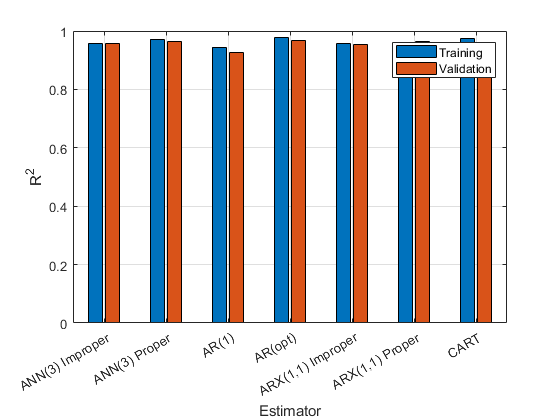

h = bar(c,r2_index);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend()
grid on

## Part 2. Dam sizing impacts